addpath('Classes')
addpath('Simulink Models')
addpath('Functions')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);

clear LMSPC_Int
clear LMSPC_PID

# Linear Moving Setpoint Controller (State Space Formulation) Class Developement Script

This script aids in the developement and documentation of the Lin_Mvng_Stpt_Cntr_SS class. 

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics
    BP_Kinetics.Derive_NL_EOMs; %Derive the nonlinear equations of motion for the ball-plate system
    BP_Kinetics.Num_Params_n_Assumptions; %Input numerical parameters and assumptions
end 

%Create a linearized EOMs object if one does not already exist. 
if (~exist('Lnrzed_EOMs', 'var')) 

    Lnrzed_EOMs = Lnrzed_EOMs(VDefs, BP_Kinetics); %Create an object of the class Lnrzed_EOMs
    Lnrzed_EOMs.Derive_8th_Ordr_Lin_Sys;
    Lnrzed_EOMs.Derive_4th_Ordr_Lin_Sys;
end 
  
%Choose a plant model symbolic variable to create a matlab function block from

% plant_model = Lnrzed_EOMs.Lin_EOMs; %Choose the linear decoupled model of the plant.
plant_model = rhs(BP_Kinetics.NL_NumEOMs); %Choose the coupled nonlinear model as the plant. Torques still approximated

if (~exist('LMSPC_Int', 'var'))

    
    LMSPC_Int = Lin_Mvng_Stpt_Cntr_SS(Lnrzed_EOMs, plant_model, VDefs, 'SS Integral Controller')

end

LMSPC_Int =   Lin_Mvng_Stpt_Cntr_SS with properties:

           sys_mats: [1×1 struct]
       sim_response: []
          ctrl_type: 'SS Integral Controller'
        stateVec_1a: [5×1 sym]
    stateVec_1a_dot: [5×1 sym]
        stateVec_2a: [5×1 sym]
    stateVec_2a_dot: [5×1 sym]
      x_setpointVec: []
      y_setpointVec: []
         sim_string: 'Linear_Moving_Setpoint_SS_Int'
              plant: [8×1 sym]



if (~exist('LMSPC_PID', 'var'))

    LMSPC_PID = Lin_Mvng_Stpt_Cntr_SS(Lnrzed_EOMs, plant_model, VDefs, 'SS PID Controller')

end

LMSPC_PID =   Lin_Mvng_Stpt_Cntr_SS with properties:

           sys_mats: [1×1 struct]
       sim_response: []
          ctrl_type: 'SS PID Controller'
        stateVec_1a: [5×1 sym]
    stateVec_1a_dot: [5×1 sym]
        stateVec_2a: [5×1 sym]
    stateVec_2a_dot: [5×1 sym]
      x_setpointVec: [3×1 sym]
      y_setpointVec: [3×1 sym]
         sim_string: 'Linear_Moving_Setpoint_SS_PID'
              plant: [8×1 sym]


## Methodology

The feasibility of a setpoint controller for trajectory tracking is explored in this script. A traditional setpoint controller architecture is employed but the setpoint is not simple. The setpoint is chosen as the desired trajectory in x and y as functions of time. 

## Augmented System For State Space Representation of an Integral Controller

### Define Augmented State Vectors


$$\tilde{x}_{1a} = [
 \int_0^t \!e_x\, \mathrm{d}t~x ~\dot{x} ~\beta~\dot{\beta}]^T


$$



$$\tilde{x}_{2a} = [
 \int_0^t \!e_y\, \mathrm{d}t~y ~\dot{y} ~\gamma~\dot{\gamma}]^T


$$


Where $e_x$ is the error in the $x$ position of the ball relative to $x_s$, the setpoint, and $e_y$ is the same for the y dimension


$$e_x = x_s - x$$



$$e_y = y_s - y$$


### Get Matrices for Augmented Dynamics

The new dynamics are found by differentiating the augmented state vectors:


$$\dot{\tilde{x}}_{1a}  = 

\left\lbrack \begin{array}{c}

e_x\\ \dot{x}\\ \ddot{x}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack

= 

\left\lbrack \begin{array}{c}

x_s - x\\ \dot{x}\\ \ddot{x}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack$$



$$\dot{\tilde{x}}_{2a}  = 

\left\lbrack \begin{array}{c}

e_y\\ \dot{y}\\ \ddot{y}\\ \dot{\gamma}\\ \ddot{\gamma}\\



\end{array}\right\rbrack

= 

\left\lbrack \begin{array}{c}

y_s - y\\ \dot{y}\\ \ddot{y}\\ \dot{\gamma}\\ \ddot{\gamma}\\



\end{array}\right\rbrack$$


This produces matrix equations with the following form:


$$\dot{\tilde{x}}_{1a} = A_{1a}\tilde{x}_{1a} + B_{1a}T_\beta + S_{1a}{x}_{s}$$



$$\dot{\tilde{x}}_{2a} = A_{2a}\tilde{x}_{2a} + B_{2a}T_\gamma + S_{2a}{y}_{s}$$


$A_{a}$ is the original $A$ matrix modified to contain the dynamics of the $\int_{0}^{t}edt~$term. This term's dynamics are the error itself, $e$, so the augmentation is simple. 

A1a_Int = LMSPC_Int.sys_mats.A1a

$$A1a\_Int = \left[\begin{array}{ccccc} 0 & -1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & -5.2170 & 0 & 4.0111 & 0\\ 0 & 0 & 0 & 0 & 1\\ 0 & 112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$

A2a_Int = LMSPC_Int.sys_mats.A2a

$$A2a\_Int = \left[\begin{array}{ccccc} 0 & -1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & -5.2170 & 0 & -4.0111 & 0\\ 0 & 0 & 0 & 0 & 1\\ 0 & -112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$

$B_{a}$ is the direct influence of the actuation torque on the system. Since the integral of the error is not a direct function of this signal, the augmented matrix recieves another zero element. 

B1a_Int = LMSPC_Int.sys_mats.B1a

$$B1a\_Int = \left[\begin{array}{c} 0\\ 0\\ -17.7268\\ 0\\ 383.5785 \end{array}\right]$$

B2a_Int = LMSPC_Int.sys_mats.B2a

$$B2a\_Int = \left[\begin{array}{c} 0\\ 0\\ 17.7268\\ 0\\ 383.5785 \end{array}\right]$$

$S_{a}$ is the matrix that tells how the setpoint enters into the dynamics. It essentially derives from the definition of the error term and partially determines the dynamics of the $\int_{0}^{t}edt~$term. 

S1a_int = LMSPC_Int.sys_mats.S1

$$S1a\_int = \left[\begin{array}{c} 1\\ 0\\ 0\\ 0\\ 0 \end{array}\right]$$

S2a_int = LMSPC_Int.sys_mats.S2

$$S2a\_int = \left[\begin{array}{c} 1\\ 0\\ 0\\ 0\\ 0 \end{array}\right]$$

The final equations of motion are:


$$

\left\lbrack \begin{array}{c}

e_x\\ \dot{x}\\ \ddot{x}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack

=

\left\lbrack \begin{array}{ccccc}
0 & -1 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0\\
0 & -5.2170 & 0 & 4.0111 & 0\\
0 & 0 & 0 & 0 & 1\\
0 & 112.8871 & 0 & 64.8295 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}

 \int_0^t \!e_x\, \mathrm{d}t\\ x\\ \dot{x}\\ \beta\\ \dot{\beta}\\



\end{array}\right\rbrack

+ 

\left\lbrack \begin{array}{c}
0\\
0\\
-17.7268\\
0\\
383.5785
\end{array}\right\rbrack


T_{\beta }

+ 

\left\lbrack \begin{array}{c}
1\\
0\\
0\\
0\\
0
\end{array}\right\rbrack


x_s\\

$$



$$

\left\lbrack \begin{array}{c}

e_y\\ \dot{y}\\ \ddot{y}\\ \dot{\gamma}\\ \ddot{\gamma}\\



\end{array}\right\rbrack

=

\left\lbrack \begin{array}{ccccc}
0 & -1 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0\\
0 & -5.2170 & 0 & -4.0111 & 0\\
0 & 0 & 0 & 0 & 1\\
0 & -112.8871 & 0 & 64.8295 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}

 \int_0^t \!e_y\, \mathrm{d}t\\ y\\ \dot{y}\\ \gamma\\ \dot{\gamma}\\



\end{array}\right\rbrack

+ 

\left\lbrack \begin{array}{c}
0\\
0\\
17.7268\\
0\\
383.5785
\end{array}\right\rbrack


T_{\gamma }

+ 

\left\lbrack \begin{array}{c}
1\\
0\\
0\\
0\\
0
\end{array}\right\rbrack


y_s\\

$$


### Output Equation

%Our desired control output is the x state (want it to match as closely as possible to x_s
%for all times)
C1a_Int = LMSPC_Int.sys_mats.C1a

$$C1a\_Int = \left[\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0 \end{array}\right]$$

C2a_Int = LMSPC_Int.sys_mats.C2a

$$C2a\_Int = \left[\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0 \end{array}\right]$$

D1a_Int = LMSPC_Int.sys_mats.D1a

D1a_Int = 0

D2a_Int = LMSPC_Int.sys_mats.D2a

D2a_Int = 0

## Place the poles of the closed loop transfer function - Integral Controller


$$\frac{{X}(s)}{X_s(s)}  = C_{a}(SI - (A_{a} - B_{a}K))^{-1}S_{a} + D_{a}$$


where the matrices all belong to the augmented state space system. The effect is to avoid having to choose an integral gain in an architecuture of the form


$$\frac{{X}(s)}{X_s(s)}  = \frac{C(s)P(s)}{1 + C(s)P(s)$$


where $C(s)$ is an integral controller, $\frac{K_i}{s}$, and $P(s)$ is the open loop plant


$$P(s) = \frac{T(s)}{X(s)} = C_a(SI - A_a)^{-1}B_a + D_a$$
 

With the augmented system, we can simply use full state feedback to arbitrarily place the poles of the integral controller rather than having to use three dimensional root locus techniques in our choice of $K_i$. 

K_Int_1 = place(double(A1a_Int),double(B1a_Int), [-10 -20 -30 -4 -5]); 
K_Int_2 = place(double(A2a_Int),double(B2a_Int), [-10 -20 -30 -4 -5]); 

### Moving Setpoint Parameters

r_sim = .1; % radius of circular trajectory [m]
omega_sim =  2*pi/3; %angular frequency of circular trajectory 

des_traj_sym_Int_x(VDefs.t) = r_sim*sin(omega_sim*VDefs.t)

$$des\_traj\_sym\_Int\_x(t) = 0.1000\,\sin\left(2.0944\,t\right)$$

des_traj_sym_Int_y(VDefs.t) = r_sim*sin(omega_sim*VDefs.t + pi/2)

$$des\_traj\_sym\_Int\_y(t) = 0.1000\,\sin\left(2.0944\,t+1.5708\right)$$

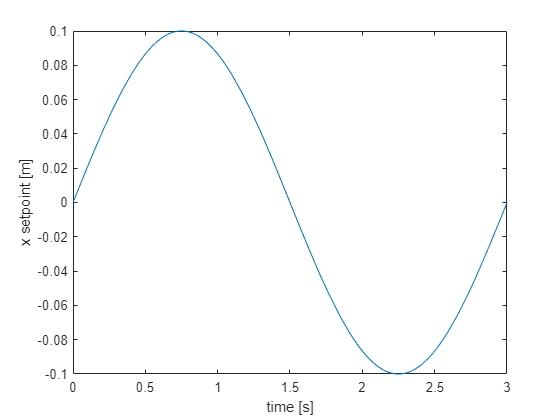


fplot(des_traj_sym_Int_x) 
xlim([0 2*pi/omega_sim]); 
ylabel('x setpoint [m]')
xlabel('time [s]')

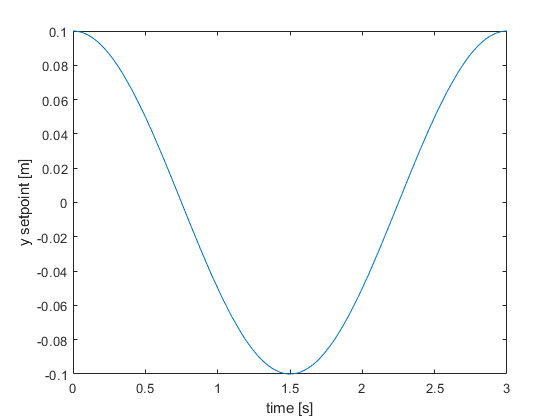


fplot(des_traj_sym_Int_y) 
xlim([0 2*pi/omega_sim]); 
ylabel('y setpoint [m]')
xlabel('time [s]')

## Simulate the Integral Controller

%Specify simulation time
tspan = [0 2*pi/omega_sim]*3;
%Specify initial conditions
x_0 = [0; 0; 0; 0; 0; 0; 0; 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system

LMSPC_Int.Run_Sim(des_traj_sym_Int_x, des_traj_sym_Int_y, tspan, x_0, K_Int_1, K_Int_2);

simout_Int_x = LMSPC_Int.sim_response

simout_Int_x =   Simulink.SimulationOutput:

                   tout: [2956x1 double] 
                      u: [2956x2 double] 
                      x: [2956x8 double] 
                    x_s: [2956x1 double] 
                    y_s: [2956x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Augmented System For State Space Representation of a PID Controller

### Define Augmented State Vectors


$$\tilde{x}_{1a} = [
 \int_0^t \!e_x\, \mathrm{d}t ~ e_x ~ e_\dot{x} ~ \beta~\dot{\beta}]^T


$$



$$\tilde{x}_{2a} = [
 \int_0^t \!e_y\, \mathrm{d}t ~ e_y ~ e_\dot{y} ~ \gamma~\dot{\gamma}]^T


$$



$$\dot{\tilde{x}}_{1a} = [
e_x ~e_\dot{x} ~ e_\ddot{x}  ~\beta~\dot{\beta}]^T$$



$$\dot{\tilde{x}}_{2a} = [
e_y ~e_\dot{y} ~ e_\ddot{y}  ~\gamma ~\dot{\gamma}]^T$$


Where $e_\dot{x}$ and $e_\dot{y}$ are the errors in the $x$ and $y$ directions, respectively


$$e_\dot{x} = \dot{x}_s - \dot{x}$$



$$e_\dot{y} = \dot{y}_s - \dot{y}$$


### Get Matrices for Augmented Dynamics

The new dynamics are found by differentiating the augmented state vector:


$$\dot{\tilde{x}}_{1a}  = 

\left\lbrack \begin{array}{c}

e_x\\ e_{\dot{x}}\\ e_{\ddot{x}}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack

= 

\left\lbrack \begin{array}{c}

x_s - x\\

\dot{x}_s - \dot{x}\\ 

\ddot{x}_s - \ddot{x}\\ 

\dot{\beta}\\ 

\ddot{\beta}\\



\end{array}\right\rbrack$$



$$\dot{\tilde{x}}_{2a}  = 

\left\lbrack \begin{array}{c}

e_y\\ e_{\dot{y}}\\ e_{\ddot{y}}\\ \dot{\gamma}\\ \ddot{\gamma}\\



\end{array}\right\rbrack

= 

\left\lbrack \begin{array}{c}

y_s - y\\

\dot{y}_s - \dot{y}\\ 

\ddot{y}_s - \ddot{y}\\ 

\dot{\gamma}\\ 

\ddot{\gamma}\\



\end{array}\right\rbrack$$


stateVec1a_PID = LMSPC_PID.stateVec_1a 

$$stateVec1a\_PID = \left[\begin{array}{c} e_{\mathrm{ix}}\\ e_{x}\\ e_{\dot{x}}\\ \beta \\ \dot{\beta } \end{array}\right]$$

stateVec2a_PID = LMSPC_PID.stateVec_2a 

$$stateVec2a\_PID = \left[\begin{array}{c} e_{\mathrm{iy}}\\ e_{y}\\ e_{\dot{y}}\\ \gamma \\ \dot{\gamma } \end{array}\right]$$

This produces matrix equations with the following form:


$$\dot{\tilde{x}}_{1a} = A_{1a}\tilde{x}_{1a} + B_{1a}T_\beta + S_{1a}{x}_{s}$$



$$\dot{\tilde{x}}_{2a} = A_{2a}\tilde{x}_{2a} + B_{2a}T_\gamma + S_{2a}{y}_{s}$$


Where $S_{1a}$ is the input matrix for the setpoint vector $\tilde{x}_{1s} = [x_s ~\dot{x}_s~\ddot{x}_s]$ for the $x$ direction. The $y$ direction is functionally identical. $A_{a}$ is the state coupling matrix for the augmented - error state vector $\tilde{x}_{a}$ and $B_{a}$ is the input matrix for torque $T$. 

stateVec1a_dot_PID = LMSPC_PID.stateVec_1a_dot 

$$stateVec1a\_dot\_PID = \left[\begin{array}{c} e_{x}\\ e_{\dot{x}}\\ e_{\ddot{x}}\\ \dot{\beta }\\ \ddot{\beta } \end{array}\right]$$

stateVec2a_dot_PID = LMSPC_PID.stateVec_2a_dot 

$$stateVec2a\_dot\_PID = \left[\begin{array}{c} e_{y}\\ e_{\dot{y}}\\ e_{\ddot{y}}\\ \dot{\gamma }\\ \ddot{\gamma } \end{array}\right]$$


A1a_PID = LMSPC_PID.sys_mats.A1a

$$A1a\_PID = \left[\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & -5.2170 & 0 & -4.0111 & 0\\ 0 & 0 & 0 & 0 & 1\\ 0 & -112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$


A2a_PID = LMSPC_PID.sys_mats.A2a

$$A2a\_PID = \left[\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & -5.2170 & 0 & 4.0111 & 0\\ 0 & 0 & 0 & 0 & 1\\ 0 & 112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$


B1a_PID = LMSPC_PID.sys_mats.B1a

$$B1a\_PID = \left[\begin{array}{c} 0\\ 0\\ 17.7268\\ 0\\ 383.5785 \end{array}\right]$$


B2a_PID = LMSPC_PID.sys_mats.B2a

$$B2a\_PID = \left[\begin{array}{c} 0\\ 0\\ -17.7268\\ 0\\ 383.5785 \end{array}\right]$$


S1a_PID = LMSPC_PID.sys_mats.S1

$$S1a\_PID = \left[\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 5.2170 & 0 & 1\\ 0 & 0 & 0\\ 112.8871 & 0 & 0 \end{array}\right]$$


S2a_PID = LMSPC_PID.sys_mats.S2

$$S2a\_PID = \left[\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 5.2170 & 0 & 1\\ 0 & 0 & 0\\ -112.8871 & 0 & 0 \end{array}\right]$$

The final equations of motion are:


$$

\left\lbrack \begin{array}{c}

e_x\\ e_{\dot{x}}\\ e_{\ddot{x}}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack

=

\left\lbrack \begin{array}{ccccc}
0 & 1 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0\\
0 & -5.2170 & 0 & -4.0111 & 0\\
0 & 0 & 0 & 0 & 1\\
0 & -112.8871 & 0 & 64.8295 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}

 \int_0^t \!e_x\, \mathrm{d}t\\ e_x\\ e_\dot{x}\\ \beta\\ \dot{\beta}\\



\end{array}\right\rbrack

+ 

\left\lbrack \begin{array}{c}
0\\
0\\
17.7268\\
0\\
383.5785
\end{array}\right\rbrack


T_{\beta }

+ 

\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
5.2170 & 0 & 1\\
0 & 0 & 0\\
112.8871 & 0 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}
x_s \\
{\dot{x} }_s \\
{\ddot{x} }_s 
\end{array}\right\rbrack

$$



$$

\left\lbrack \begin{array}{c}

e_y\\ e_{\dot{y}}\\ e_{\ddot{y}}\\ \dot{\gamma}\\ \ddot{\gamma}\\



\end{array}\right\rbrack

=

\left\lbrack \begin{array}{ccccc}
0 & 1 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0\\
0 & -5.2170 & 0 & 4.0111 & 0\\
0 & 0 & 0 & 0 & 1\\
0 & 112.8871 & 0 & 64.8295 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}

 \int_0^t \!e_y\, \mathrm{d}t\\ e_y\\ e_\dot{y}\\ \gamma\\ \dot{\gamma}\\



\end{array}\right\rbrack

+ 

\left\lbrack \begin{array}{c}
0\\
0\\
-17.7268\\
0\\
383.5785
\end{array}\right\rbrack


T_{\gamma }

+ 

\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
5.2170 & 0 & 1\\
0 & 0 & 0\\
-112.8871 & 0 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}
y_s \\
{\dot{y} }_s \\
{\ddot{y} }_s 
\end{array}\right\rbrack

$$


### Output Equation

%Our desired control output is the x or y state (want it to match as closely as possible
%to x_s or y_s for all times). Given that x = x_s - e_x, and y = y_s - e_y, C and D are:
C1a_PID = LMSPC_PID.sys_mats.C1a 

C1a_PID =      0    -1     0     0     0


D1a_PID = LMSPC_PID.sys_mats.D1a 

D1a_PID =      1     0     0



C2a_PID = LMSPC_PID.sys_mats.C2a 

C2a_PID =      0    -1     0     0     0


D2a_PID = LMSPC_PID.sys_mats.D2a 

D2a_PID =      1     0     0


### Find Derivative of Trajectory

des_traj_sym_dot_Int_x(VDefs.t) = diff(des_traj_sym_Int_x(VDefs.t),VDefs.t)

$$des\_traj\_sym\_dot\_Int\_x(t) = 0.2094\,\cos\left(2.0944\,t\right)$$

des_traj_sym_dot_Int_y(VDefs.t) = diff(des_traj_sym_Int_y(VDefs.t),VDefs.t)

$$des\_traj\_sym\_dot\_Int\_y(t) = 0.2094\,\cos\left(2.0944\,t+1.5708\right)$$


%Create function handles from the desired trajectory information
des_traj_sym_PID_x = [des_traj_sym_Int_x;des_traj_sym_dot_Int_x]

$$des\_traj\_sym\_PID\_x(t) = \left[\begin{array}{c} 0.1000\,\sin\left(2.0944\,t\right)\\ 0.2094\,\cos\left(2.0944\,t\right) \end{array}\right]$$

des_traj_sym_PID_y = [des_traj_sym_Int_y;des_traj_sym_dot_Int_y]

$$des\_traj\_sym\_PID\_y(t) = \left[\begin{array}{c} 0.1000\,\sin\left(2.0944\,t+1.5708\right)\\ 0.2094\,\cos\left(2.0944\,t+1.5708\right) \end{array}\right]$$

### Place the poles of the closed loop transfer function 


$$\frac{{X_s}(s)}{X(s)}  = C_{a}(SI - (A_{a} - B_{a}K))^{-1}S_{a} + D_{a}$$


where the matrices all belong to the augmented state space system. The effect is to avoid having to choose PID gains in an architecuture of the form


$$\frac{{X_s}(s)}{X(s)}  = \frac{C(s)P(s)}{1 + C(s)P(s)$$


where $C(s)$ is a PID controller and $P(s)$ is the open loop plant


$$P(s) = \frac{T_{\beta}(s)}{X(s)} = C_a(SI - A_a)^{-1}B_a$$
 

At the very least, this provides for bounded input - bounded output stability. However, this tells us nothing directly about the tracking performance of the controller. With the augmented system, we can simply use full state feedback to arbitrarily place the poles of the PID controller rather than having to use three dimensional root locus techniques in our choice of $K_i, ~K_p, ~and~K_d$. 

K_PID1 = place(double(A1a_PID),double(B1a_PID), [-10 -20 -30 -4 -5])

K_PID1 =   -44.6463  -28.5703   -6.6566    5.8034    0.4875


K_PID2 = place(double(A2a_PID),double(B2a_PID), [-10 -20 -30 -4 -5])

K_PID2 =    44.6463   28.5703    6.6566    5.8034    0.4875



% K_PID = place(double(A1a_PID),double(B1a_PID), [-10 -20 -30 -4 -5]/3)

% K_PID = [-10 -87.2359 -46.5577 87.0181 12.6186]; %Testing Zach's gains (with my integral gain in there)

% Q_e_ix = 1/5^2;
% Q_e_x = 1/.005^2;
% Q_e_xd = 1/.010^2; 
% Q_b = 1/deg2rad(25)^2; 
% Q_bd = 1/omega_sim^2;
% 
% Q = [Q_e_ix 0 0 0 0; 
%      0 Q_e_x 0 0 0;
%      0 0 Q_e_xd 0 0;
%      0 0 0 Q_b 0;
%      0 0 0 0 Q_bd];
% 
% R = 1/73^2; %2
% 
% [K_PID,S,e] = lqr(double(A1a_PID), double(B1a_PID), Q,R);
% K_PID

## Simulate the PID Controller

%Specify simulation time
tspan = [0 2*pi/omega_sim]*3;
% tspan = [0 2] %For checking Zach's regulator gains
%Specify initial conditions
x_0 = [0; 0; 0; 0; 0; 0; 0; 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system
% xa_0 = [0 -.2 0 0 0]; %Checking Zach's regulator gains

LMSPC_PID.Run_Sim(des_traj_sym_PID_x,des_traj_sym_PID_y, tspan, x_0, K_PID1, K_PID2);

simout_PID_x = LMSPC_PID.sim_response

simout_PID_x =   Simulink.SimulationOutput:

                   tout: [298x1 double] 
                      u: [298x2 double] 
                      x: [298x8 double] 
                x_s_vec: [298x2 double] 
                y_s_vec: [298x2 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Compare the Responses

### Raw Simulation Data Plotted

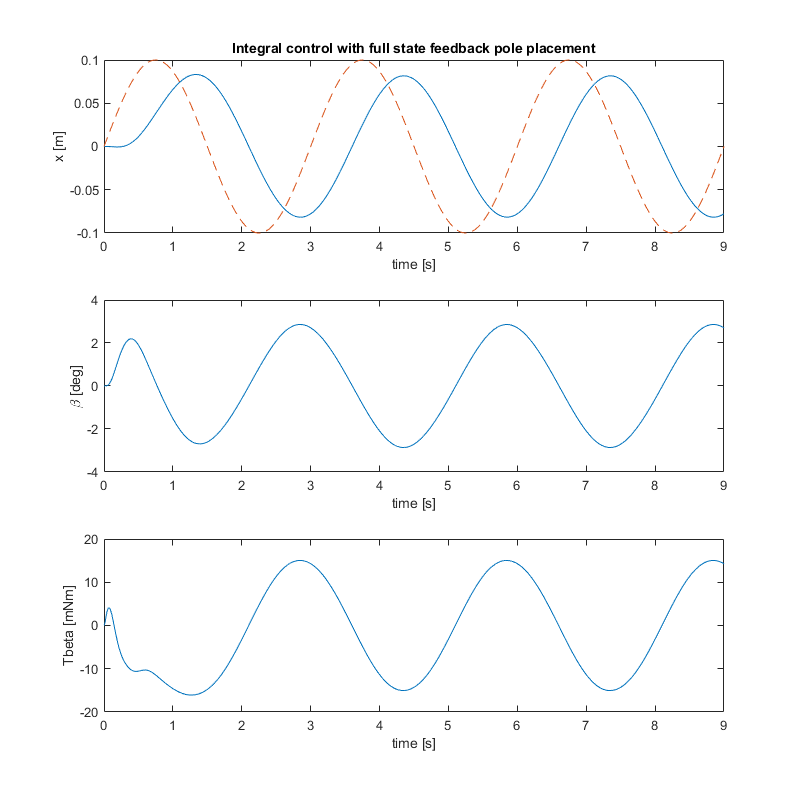

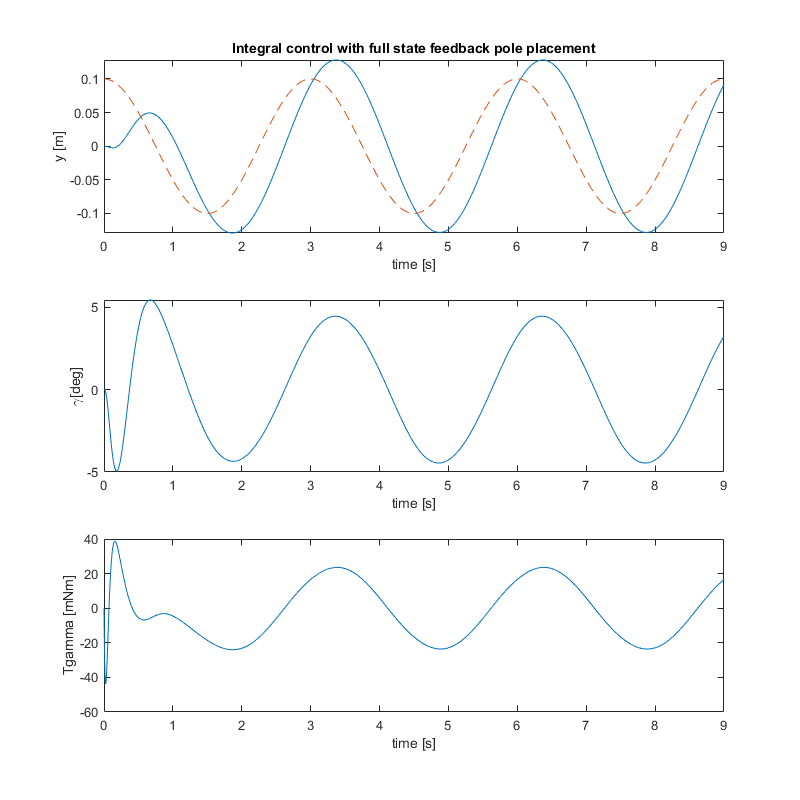

%Plot the integral controller results

Int_fig = LMSPC_Int.plot_results('Integral control with full state feedback pole placement');

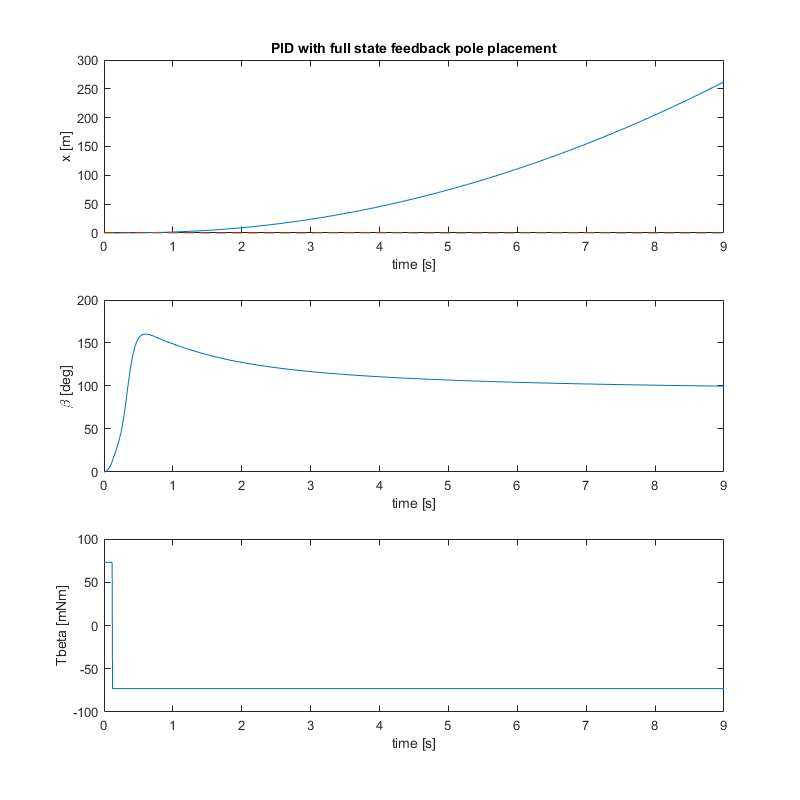

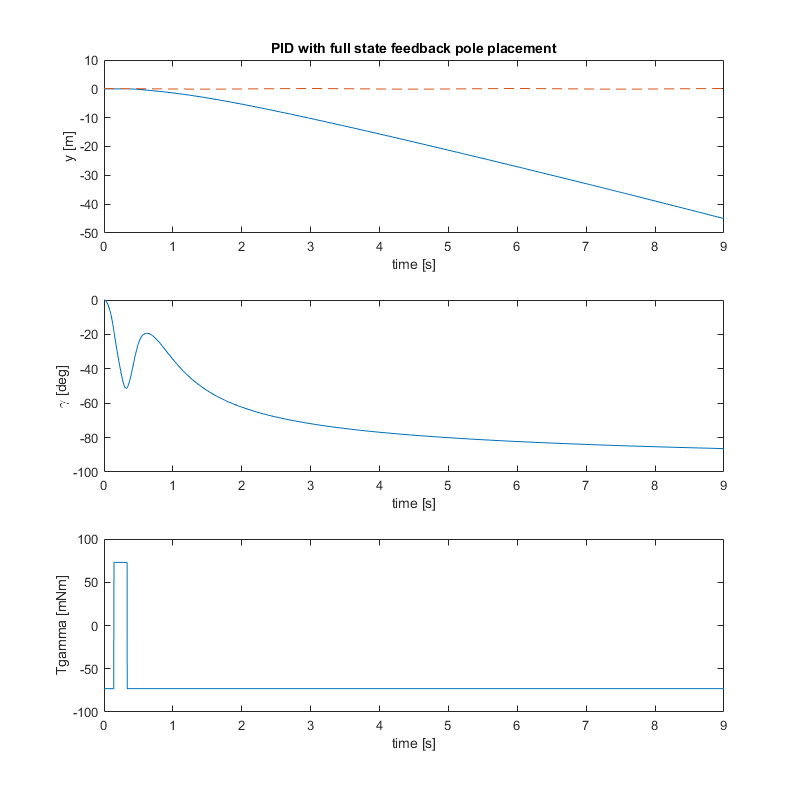




% %Plot the PID controller results
PID_fig = LMSPC_PID.plot_results('PID with full state feedback pole placement');

## Animate Responses

% Animate_Response(simout_PID_x.